PathsDan = 'E:\Motorcycle\Data\MatLab\Mixail';
NameFile = 'FMixa.mat'

NameFile = 'FMixa.mat'

PathFile = PathsDan+"\"+NameFile

PathFile = "E:\Motorcycle\Data\MatLab\Mixail\FMixa.mat"

load('-mat', PathFile)
Acc = double(FMixa.AC_pwrAct(1:length(FMixa.AC_pwrAct)-2));


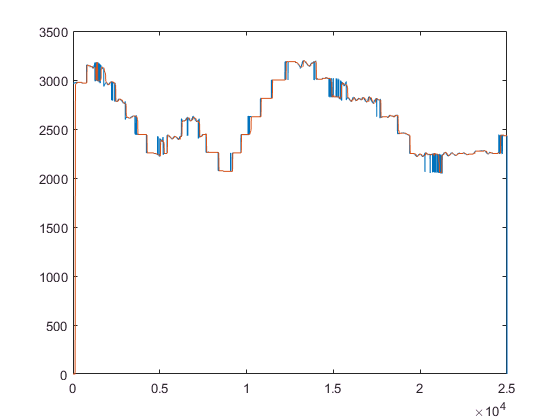

sig= SigmoidMixail(50);
Result= sig.CalcSignal(Acc);
t0=1:length(Acc);
%plot(Result.rez)
t0=1:length(Acc);
z=ema(Result.rezU, 5);
plot(t0, Acc, t0, z);

t0=1:length(Acc);
tAcc=zeros(length(Acc), 2);
tAcc(:,1)=t0';
tAcc(:,2)=Acc';


%  формируем данные для теста в Simulink
m0=[0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0;0]
Acc3=[m0', Acc, m0'];
t03=0:0.01:(length(Acc3)-1)*0.01

t03 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


tAcc03(:, 1)=t03';
tAcc03(:, 2)=Acc3';


tAcc1(:,:)=tAcc(1:9600,:);

% Test MixFiltrSig <--  Simulink
sigFiltr = MixFiltrSig()

sigFiltr =   MixFiltrSig with properties:

           M1: [51×1 double]
      M1count: 51
           M2: [29×1 double]
      M2count: 29
           M3: [15×1 double]
      M3count: 15
      myFront: [1×1 struct]
    mySigmoid: [1×1 struct]
        point: [1×1 struct]
          ind: [1×1 struct]
            i: 0
            j: 0
            k: 0
        u_tek: 0
      u_delta: 0
         u_sm: 0
      u_sig_k: 0
        y_old: 0
         nEma: 0
     alfa_ema: 0


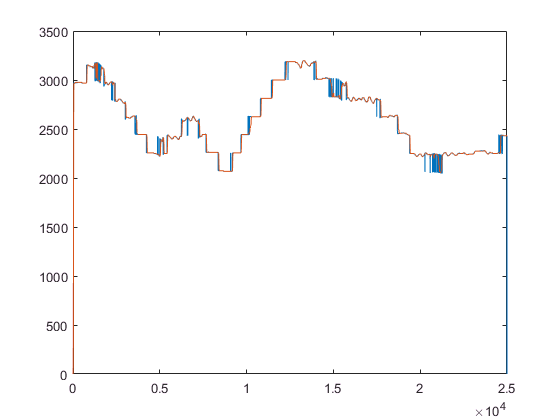

%sigFiltr.setupImpl();
rez=zeros(length(Acc), 1);

for i=1:length(Acc)
    rez(i, 1) = sigFiltr.stepImpl(Acc(i));    
end
plot(t0, Acc, t0, rez(:,1));

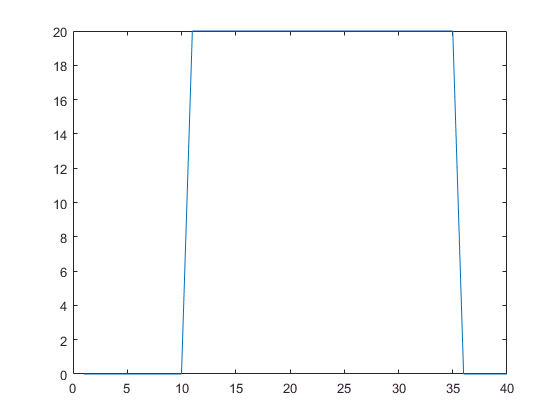

mSig(1:10) = 0;
mSig(11:35) = 20;
mSig(36:40) = 0;
plot(mSig)

t01=1:length(mSig);
tImpuls = zeros(length(mSig), 2);
tImpuls(:,2) = mSig;
tImpuls(:,1) = t01;


i0=0;
for i=1:length(mSig)
    if mSig(i)>0
        i0=i0+1
        tImpuls(i,2) = i0;       
    else
        tImpuls(i,2) = i0;       
    end
end

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 1

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 2

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 3

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 4

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 5

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 6

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 7

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 8

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 9

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 10

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 11

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 12

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 13

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 14

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 15

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 16

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 17

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 18

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 19

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 20

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 21

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 22

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 23

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 24

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


i0 = 25

tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


tImpuls =      1     0
     2     0
     3     0
     4     0
     5     0
     6     0
     7     0
     8     0
     9     0
    10     0


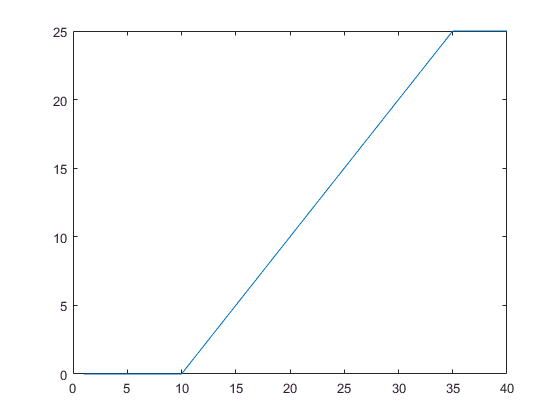


plot(tImpuls(:,2))

function z=ema(y, nCount)
    yCount=length(y);
    z=zeros(yCount, 1);
    z(1)=y(1);
    alfa=2/(nCount+1);
    alfa1=(1-alfa);
    for i=2:1:yCount
      z(i)=alfa*y(i)+alfa1* z(i-1); 
    end
end